clear all;close all;
%just open folder with data in it in matlab and run the script 
%make sure the filename is like date_sample_structures_contactspecification(_size).format
format='*.txt';            %fileformat that is currently processed is .txt
N=5;                      %fit from ni-N to ni+N
n=1;                       %degree of fitpolynome
safeplots=0;               %1: safe 0: dont safe
plottitle='Illuminated';   %Plottitle for plot with all curves
poi='max';                  %POI for evaluation at either 'zero' or 'max'=10V
    
%   all files from the directory that is currently openend in MATLAB
filestruct=dir(format);
files={filestruct.name};


% Distance between contacts L, Circumference of contacts U and Area of contacts A.
L=zeros(1,length(files));
U=zeros(1,length(files));
A=zeros(1,length(files));
for i=1:length(files)
    C = regexp(char(files(i)), '_', 'split');
    sample=string(C{2});
    structure=string(C{3});
    field=char(C{4});    
    if structure=='TLM'
        L(i) = str2num(C{4}); 
    elseif structure=='Stripes'
        L(i) = 200;
    try 
    size=char(C{5});
    size=size(1:end-4);
    catch
        field=field(1:end-4);
        switch field
            case '7-7' 
                U(i)=1.7;  A(i)=0.04; 
            case '8-8' 
                U(i)=3.7;  A(i)=0.09; 
            case '9-9' 
                U(i)=2.55;  A(i)=0.09; 
            case '10-10' 
                U(i)=4.416;  A(i)=0.16;
        end
    end
    switch field
        case '1-1'
            switch size
                case 'S' 
                    U(i)=0.3;  A(i)=0.005;
                case 'M' 
                    U(i)=0.35; A(i)=0.0075;
                case 'L' 
                    U(i)=0.4;  A(i)=0.01; 
            end 
        case '2-2'
            switch size
                case 'S'
                    U(i)=0.4;  A(i)=0.0075; 
                case 'M'  
                    U(i)=0.45; A(i)=1.5*0.0075; 
                case 'L'  
                    U(i)=0.5;  A(i)=2*0.0075; 
            end
            
        case '3-3' 
            switch size
                case 'S'  
                    U(i)=0.5;  A(i)=0.01; 
                case 'M'  
                    U(i)=0.55; A(i)=1.5*0.01; 
                case 'L'  
                    U(i)=0.6;  A(i)=0.02; 
            end
            
        case '4-4' 
            switch size
                case 'S'  
                    U(i)=0.7;  A(i)=0.015; 
                case 'M'  
                    U(i)=0.75; A(i)=1.5*0.015; 
                case 'L'  
                    U(i)=0.8;  A(i)=0.03; 
            end 
            
        case '5-5' 
            switch size
                case 'S'  
                    U(i)=0.9;  A(i)=0.02; 
                case 'M'  
                    U(i)=0.95; A(i)=1.5*0.02; 
                case 'L'  
                    U(i)=1.0;  A(i)=0.04; 
            end
            
        case '6-6' 
            switch size
                case 'S'  
                    U(i)=1.1;  A(i)=0.025; 
                case 'M'  
                    U(i)=1.15; A(i)=1.5*0.025; 
                case 'L'  
                    U(i)=1.2;  A(i)=0.05; 
            end  
    end
    elseif structure=='Areas'
    field=field(1:end-4);
        switch field
            case '1-1'
                U(i)=0.4; A(i)=0.01;
            case '2-2'
                U(i)=0.6; A(i)=0.0225;
            case '3-3'
                U(i)=0.8; A(i)=0.04;
            case '4-4'
                U(i)=1.2; A(i)=0.09;
            case '5-5'
                U(i)=1.6; A(i)=0.16;
            case '6-6'
                U(i)=2.0; A(i)=0.25;
        end
    end
end



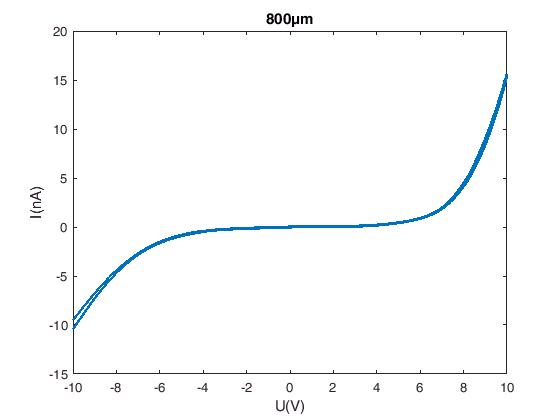

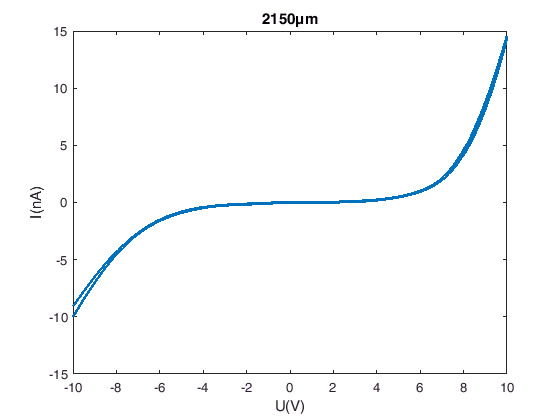

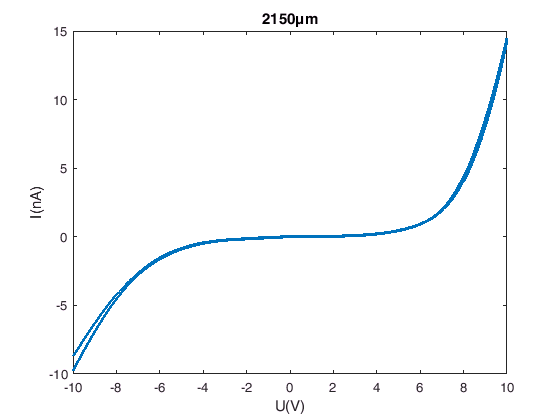

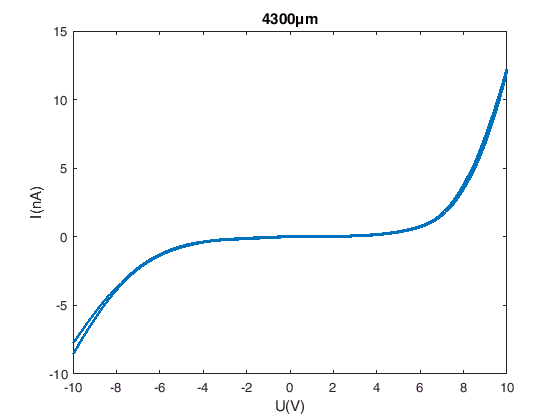

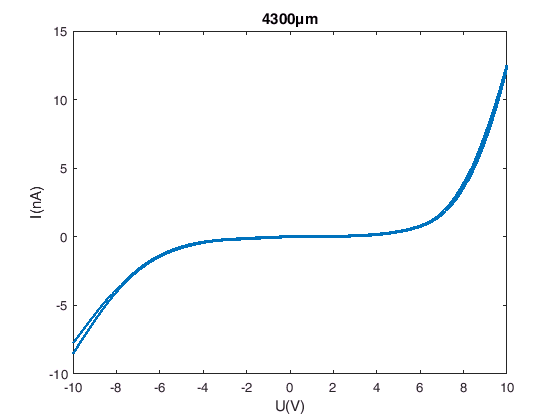

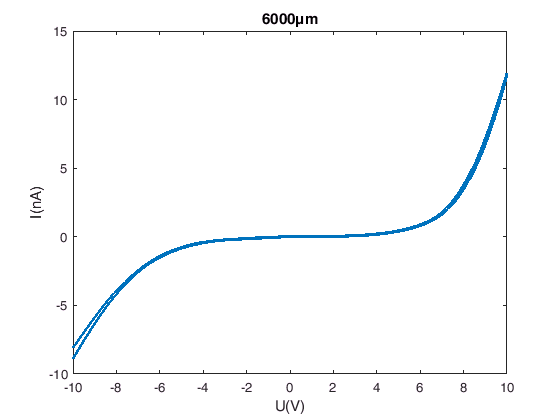

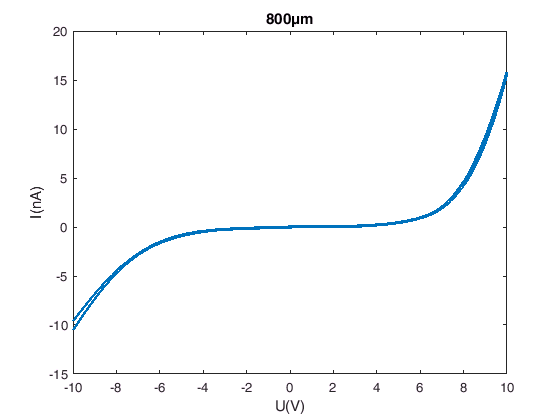

%Plots

legendL={};
for i=1:length(files)
    fig=figure();
    Data=importdata(char(files(i)));   % data file 
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    plot(Data.data(:,1) , 10^9*Data.data(:,2),'LineWidth',2);
    if structure=='TLM'
        title(strcat(string(L(i)),'µm'));
        legendL=[legendL,char(strcat(string(L(i)),'µm'))];
    else
        title(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'));
        legendL=[legendL,char(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'))];
    end
    xlabel('U(V)');
    ylabel('I(nA)');
    hold off
    if safeplots==1
        mkdir('plots/single');
        saveas(fig,['plots/single/' char(files(i)) '.pdf']);
    end
end

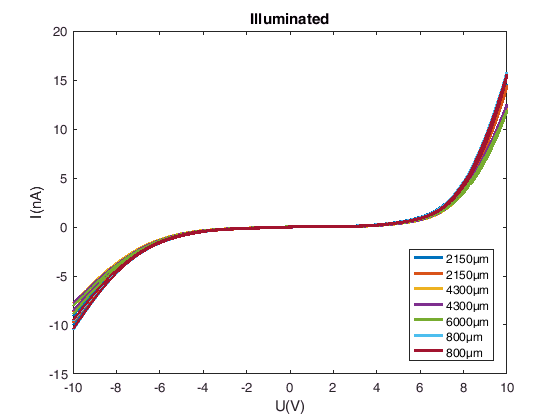


for i=1:length(files)
    Data=importdata(char(files(i)));
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    plot(Data.data(:,1) , 10^9*Data.data(:,2),'LineWidth',2);
    hold on
end

xlabel('U(V)');
ylabel('I(nA)');
title(plottitle);

legend(legendL,'Location','southeast');


if safeplots==1
    saveas(fig,'plots/all_distances.pdf');
end

%Fitting

R=zeros(length(files),2);
dR=zeros(length(files),2);
% fig2=figure();
for i=1:length(files)
   
    xlabel('U(V)');
    ylabel('I(nA)');
    hold on
    
    Data=importdata(char(files(i)));
    Data.data(:,[1 2]) = Data.data(:,[2 1]);
    
    if poi==string('zero')
  
       
        n1=round(1/4*length(Data.data));    %U=0 datapoint
        n2=round(3/4*length(Data.data));    %U=0 datapoint
        fitdat1=[Data.data((n1-N):(n1+N),1),10^9*Data.data((n1-N):(n1+N),2)];
        fitdat2=[Data.data((n2-N):(n2+N),1),10^9*Data.data((n2-N):(n2+N),2)];
        
        fig2=figure();
        if structure=='TLM'
            title(strcat(string(L(i)),'µm'));       
        else
            title(strcat(string(U(i)),'mm',', ',string(A(i)),'mm²'));
        end
     
    %     Linear fit
    % 
    %     scatter(fitdat1(:,1),fitdat1(:,2));
    %     scatter(fitdat2(:,1),fitdat2(:,2));
    %     h=lsline;
    %     
    %     R(i,1)=(h(1,1).XData(2)-h(1,1).XData(1))/(h(1,1).YData(2)-h(1,1).YData(1));
    %     R(i,2)=(h(1,2).XData(2)-h(1,2).XData(1))/(h(1,2).YData(2)-h(1,2).YData(1));
    %     
    %     legend(strcat('R=',string(R(i,2)),' G\Omega'),strcat('R=',string(R(i,1)),' G\Omega'),'Location','northwest')
    
    %    Polynomial fit
        [p1,S1]=polyfit(fitdat1(:,1),fitdat1(:,2),n); % - -> + sweep 
        [p2,S2]=polyfit(fitdat2(:,1),fitdat2(:,2),n); % + -> - sweep
        
        f1=polyval(p1,fitdat1(:,1));
        f2=polyval(p2,fitdat2(:,1));
        
    %         inv(S#.R)*inv(S#.R)')*S#.normr^2/S#.df covariance matrix
        covp1=(inv(S1.R)*inv(S1.R)')*S1.normr^2/S1.df;
        covp2=(inv(S2.R)*inv(S2.R)')*S2.normr^2/S2.df;
        dp1=sqrt(covp1(n,n));
        dp2=sqrt(covp2(n,n));
    
        R(i,1)=1/p1(n);
        dR(i,1)=dp1/p1(n)^2;
        R(i,2)=1/p2(n);
        dR(i,2)=dp2/p2(n)^2;
    
        plot(fitdat1(:,1),fitdat1(:,2),'o',fitdat1(:,1),f1,'-',fitdat2(:,1),fitdat2(:,2),'o',fitdat2(:,1),f2,'-');
        legend('- -> + data',strcat('R=',string(R(i,2)),' G\Omega'),'+ -> - data',strcat('R=',string(R(i,1)),' G\Omega'),'Location','northwest')
    
        if safeplots==1
        mkdir('plots/fits');
        saveas(fig2,['plots/fits/' char(files(i)) '.pdf']);
        end
    elseif poi==string('max')
        
        n1=round(1);    %U=-10V datapoint1
        n2=round(length(Data.data));    %U=-10V datapoint2
        n3=round(1/2*length(Data.data));    %U=10V datapoint1
        n4=round(1/2*length(Data.data))-1;    %U=10V datapoint2
        
        R(i,1)=10^-9*(Data.data(n1,1)/Data.data(n1,2)+Data.data(n2,1)/Data.data(n2,2))/2; 
        R(i,2)=10^-9*(Data.data(n3,1)/Data.data(n3,2)+Data.data(n4,1)/Data.data(n4,2))/2;
        dR(i,1)=R(i,1)*0.04;
        dR(i,2)=R(i,2)*0.04;
    end
    
    
end

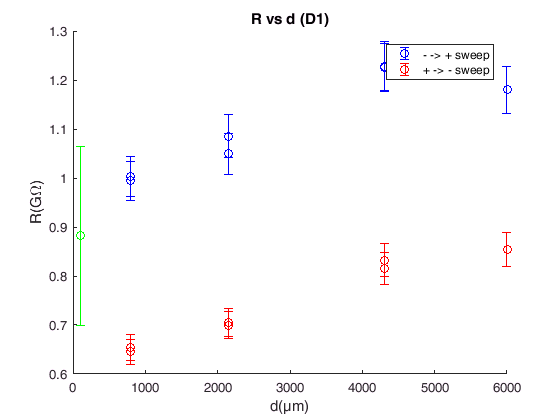

R_mean = 0.8816

sigma = 0.1832

%Plotting results for R
fig3=figure();
hold on
if structure=='TLM'
    errorbar(L(:),R(:,1),dR(:,1),'bo'); errorbar(L(:),R(:,2),dR(:,2),'ro')
    title(strcat('R vs d (',sample,')'));
    xlabel('d(µm)');
    ylabel('R(G\Omega)');
    legend('- -> + sweep','+ -> - sweep','Location','northeast')
    else
        errorbar(A(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo'); errorbar(A(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro')
        title(strcat('G vs A (',sample,')'));
        xlabel('A(mm²)');
        ylabel('G(G\Omega^{-1})');
        legend('- -> + sweep','+ -> - sweep','Location','northeast')
        
        fig4=figure();
        hold on
        errorbar(U(:),1./R(:,1),dR(:,1)./R(:,1).^2,'bo'); errorbar(U(:),1./R(:,2),dR(:,2)./R(:,1).^2,'ro')
        title(strcat('G vs Umfang (',sample,')'));
        xlabel('Umfang(mm)');
        ylabel('G(G\Omega^{-1})');
        legend('- -> + sweep','+ -> - sweep','Location','northeast')
    end

if safeplots==1
    saveas(fig3,['plots/fits/G_vs_A.pdf']);
    try saveas(fig4,['plots/fits/G_vs_Umfang.pdf']); end
end
%weighted mean 
if structure=='TLM'
R_mean=sum(sum(R*1./dR))/(sum(sum(1./dR)))
sigma=sqrt(sum(sum(1./dR))/(sum(sum(1./(dR.^2)))))
errorbar(100,R_mean,sigma,'go');
end